# On the Optimality of Spectrally Notched Radar Waveform & Filter Designs

Jonathan W. Owen, Patrick M. McCormick, Christian C. Jones, Shannon D. Blunt, Radar Systems Lab (RSL), University of Kansas, Lawrence, KS

M = 256; % signal length

% Desired Autocorrelation (all zeros except a single one)
desiredAutocorr = zeros(M,1);
desiredAutocorr(1) = 1;

% Inverse DFT matrix
% A is the inverse DFT matrix which is just the Hermitian transpose of the DFT matrix
% I also normalize it by M
A = dftmtx(M)'/M;

% Spoiling the IDFT matrix
% < 0 means no spoiling
n = 0;
Aspoil = A;
if n > 0
    Aspoil(2:2+n-1,:) = 0;
    Aspoil(end-n+1:end,:) = 0;
end


## Objective Function

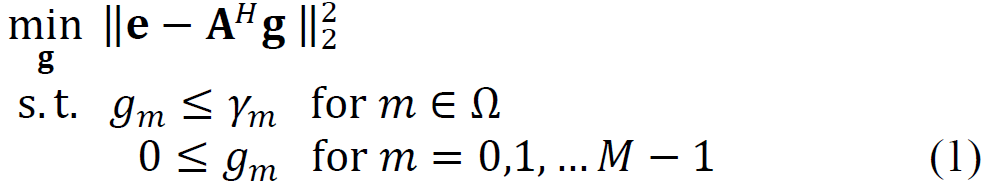

**e** is the desired autocorrelation function

**g** is the power spectral density (PSD) of the waveform

The PSD is the Fourier Transform of the autocorrelation. Thus, we are minimizing the difference between the desired autocorrelation and the autocorrealtion of the waveform with PSD, **g**.

The first inequality constraint is 

% Equation 1 in paper
% g is the desired PSD which is the FT of the autocorelation
fun = @(g)norm(desiredAutocorr-Aspoil*g,2);

lb = zeros(size(desiredAutocorr));
ub = inf(size(desiredAutocorr));
nullHeight = db2pow(-30);
ub(1:25) = nullHeight;
ub(100:140) = nullHeight;
ub(end-25:end) = nullHeight;


x0 = zeros(size(desiredAutocorr));
options = optimoptions('fmincon',MaxFunctionEvaluations=100000);
g = fmincon(fun,x0,[],[],[],[],lb,ub,[],options);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


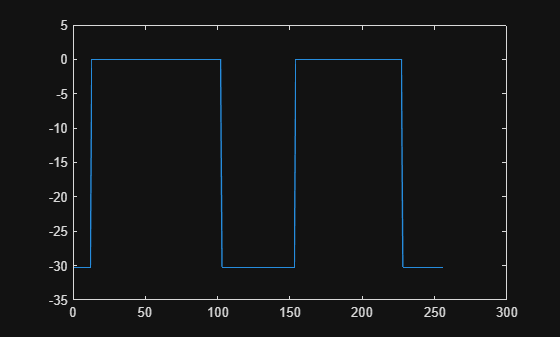

figure;
plot(fftshift(pow2db(g)))

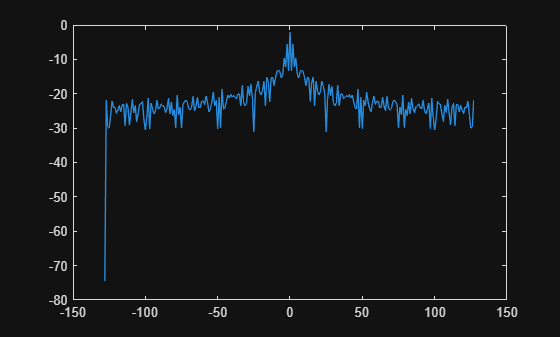

figure
plot(-M/2:M/2-1,pow2db(fftshift(abs(A'*g))));